clear all; clc;

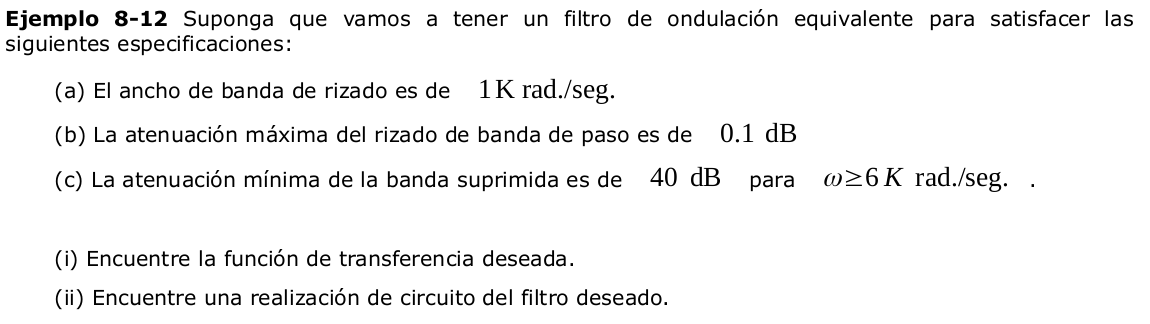

**Datos**

wp_=1E3;    % banda de paso
ws_=6E3;    % banda de rechazo
As=40;      % atenuación
Ap=0.1;     % banda de paso

Normalizar las especificaciones

ws=ws_/wp_;

**Cálculo del ripple**

ripple=@(A) sqrt(10^(A/10)-1);
orden=@(A,w,A2) acosh( ripple(A )/ripple(A2) )/acosh(w );
e=ripple(Ap)

e = 0.1526

**Cálculo de orden**

n1=orden(As,ws,Ap);

n=ceil(n1)

n = 3

**Cálculo de la función de transferencia **

**1- Opción 1. A partir de los polos**

syms w 'real'
T=0;
[T]=Chebyshev(w, n);
D(w)=collect(1 + e^2*T^2);
syms s;
H2(s)=1/D(s/j)

$$H2(s) = -\frac{1}{0.3727\,s^{6}+0.5590\,s^{4}+0.2096\,s^{2}-1}$$

r=roots(sym2poly(D(s)));
q=[];w=1;
for m=1:length(r)
    if real(r(m))<0 
        q(w)=r(m);
        w=w+1;
    end
end
H(s)=1/collect( prod(s- q(:)) )

$$H(s) = \frac{1}{s^{2}+2.4123\,s+1.6897}$$

**2- Opción 2. A partir de los polos**

syms k 'integer';
syms s;

beta=asinh(1/e)/n

beta = 0.8596

theta(k)=(2*k-1)/(2*n)*pi;
sk(k)=sinh( beta )*sin( theta(k) ) +j*cosh( beta )*cos( theta(k) )

$$sk(k) = 0.9694\,\sin\left(1.0472\,k-0.5236\right)+1.3927\,\cos\left(1.0472\,k-0.5236\right)\,\mathrm{i}$$


abs(sk(4:6))

$$ans = \left(\begin{array}{ccc} 1.2999 & 0.9694 & 1.2999 \end{array}\right)$$

angle(sk(4:6))

$$ans = \left(\begin{array}{ccc} -1.9529 & 3.1416 & 1.9529 \end{array}\right)$$


D(s)=prod(s-sk(4:6));
D(s)=collect(D(s));
H(s)=1.6381/vpa(D(s),3)

$$H(s) = \frac{1.6381}{s^{3}+1.9388\,s^{2}+2.6295\,s+1.6381}$$

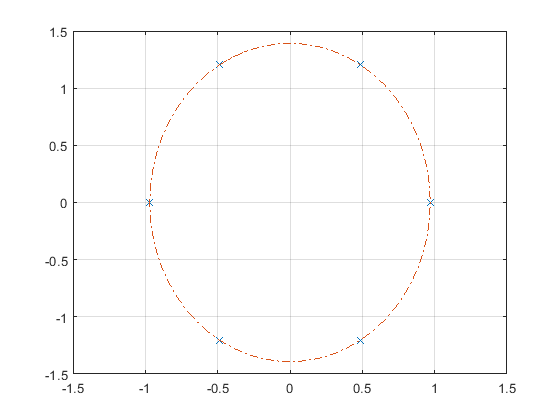

m=0:0.1:2*pi;
plot(real(sk(1:6)), imag(sk(1:6)),'X'), hold on, ...
plot( sk(m),'-.' ), hold off; ...
xlim([-1.5,1.5]); grid on;

%[b,a]=numden(collect(H(s))); B=sym2poly(b); A=sym2poly(a);
%freqs(B,A)
plotdb(collect(H(s)), -1,1); title('Filtro Pasa bajos (band pass)');



**Transformación de paso bajo a paso bajos**

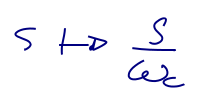

Hbp(s)=H(s/wp_)

$$Hbp(s) = \frac{1.6381}{1.0000e-09\,s^{3}+1.9388e-06\,s^{2}+0.0026\,s+1.6381}$$

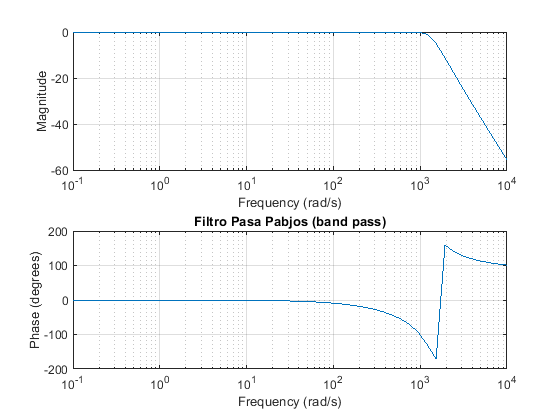

%[b,a]=numden(collect(H(s))); B=sym2poly(b); A=sym2poly(a);
%freqs(B,A)
plotdb(collect(Hbp(s)), -1,4); title('Filtro Pasa Pajos (band pass)');



%%polinomio de chebyshev

function [T]=Chebyshev(w,n)
  if n==0
    T=1;
  elseif n==1
    T=w;
  else
    T=2*w*Chebyshev(w,n-1)-Chebyshev(w,n-2);
  end
end
